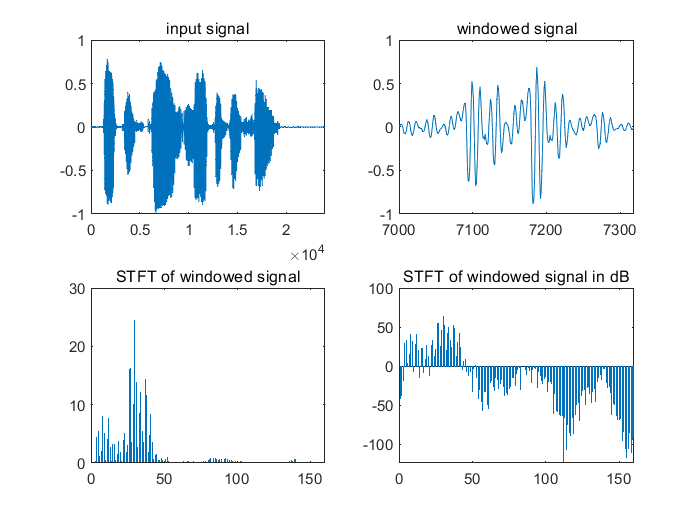

figure()
q1('s5.wav',7000,40);

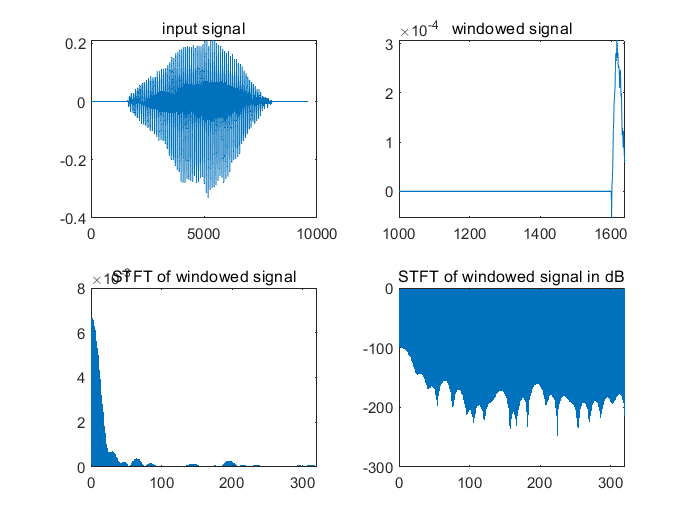

figure()
q1('vowel_iy_100hz.wav',1000,40);

function [ ] = q1( file_name, start_sample, frame_length )
[signal, Fs] = audioread(file_name);
L = round((Fs/1000)*frame_length);
window = hamming(L);

% plot the original signal
subplot(2,2,1);plot(signal);title('input signal');

% plot the windowed signal
signal_w = signal(start_sample:start_sample+L-1).*window;
subplot(2,2,2);plot(start_sample:start_sample+L-1,signal_w);title('windowed signal');

% plot the STFT
signal_w_s = fft(signal_w);
subplot(2,2,3);stem(abs(signal_w_s(1:round(L/2))),'Marker','none');title('STFT of windowed signal');

% plot the STFT in dB
signal_w_s_db = 20*log(abs(signal_w_s));
subplot(2,2,4);stem(signal_w_s_db(1:round(L/2)),'Marker','none');title('STFT of windowed signal in dB');

end